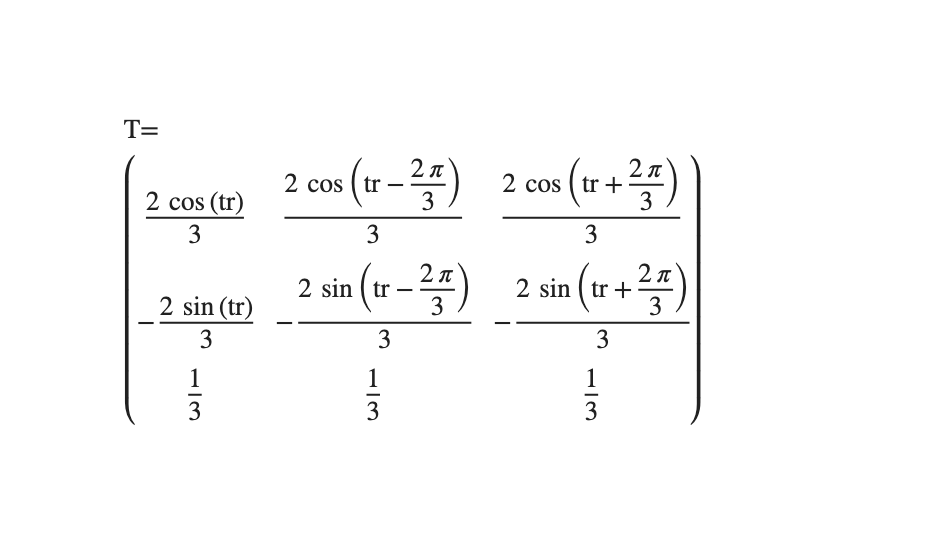

clear; close all;

J = [0 -1 0; 1 0 0; 0 0 0];
% w = 2*pi*60;

syms t;
syms Lls LA LB tr Lsf theta(t) w;
L_diag = @(phase) Lls+LA+LB*cos(2*(tr+phase));
L_not_diag = @(phase) -1/2*LA+LB*cos(2*(tr+phase));

a = 2*pi/3;

Lss = [L_diag(0) L_not_diag(a) L_not_diag(-a);
      L_not_diag(a) L_diag(-a) L_not_diag(0);
      L_not_diag(-a) L_not_diag(0) L_diag(a);];
Lfs = Lsf*[cos(tr); cos(tr-a); cos(tr+a);];

T = [cos(tr)  cos(tr-a)  cos(tr+a);
    -sin(tr) -sin(tr-a) -sin(tr+a);
    1/2            1/2         1/2;] *2/3;

set(gcf, 'Name', 'Transformation expression', 'NumberTitle', 'off'); 
axis off;
text(0, 0.5,['T= ' '$$' latex(T) '$$'], 'interpreter', 'latex');



L_dq = simplify( T*Lss*inv(T) )

$$L\_dq = \left(\begin{array}{ccc} \frac{3\,\mathrm{LA}}{2}+\frac{3\,\mathrm{LB}}{2}+\mathrm{Lls} & 0 & 0\\ 0 & \frac{3\,\mathrm{LA}}{2}-\frac{3\,\mathrm{LB}}{2}+\mathrm{Lls} & 0\\ 0 & 0 & \mathrm{Lls} \end{array}\right)$$

여기서 L_dq(1,1)은 Lds, L_dq(2,2)는 Lqs라고 하자.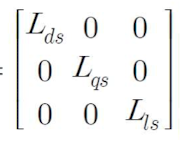 

syms Lds Lqs
L_dq = diag([Lds Lqs Lls])

$$L\_dq = \left(\begin{array}{ccc} \mathrm{Lds} & 0 & 0\\ 0 & \mathrm{Lqs} & 0\\ 0 & 0 & \mathrm{Lls} \end{array}\right)$$

Lfw = simplify( T*Lfs )

$$Lfw = \left(\begin{array}{c} \mathrm{Lsf}\\ 0\\ 0 \end{array}\right)$$

syms id iq
I_dq = [id; iq; 0]; % dqn current

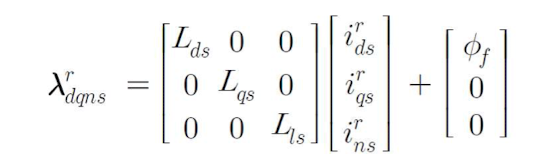

lambda_dq = L_dq*I_dq + Lfw; % 문제3.5 SynRM은 Lfw =0, 즉 계자 플럭스가 0이다.

V_dq = w*J*lambda_dq % 정상상태라고 가정. #미분항 제외 #저항은 매우 작다

$$V\_dq = \left(\begin{array}{c} -\mathrm{Lqs}\,\mathrm{iq}\,w\\ w\,\left(\mathrm{Lsf}+\mathrm{Lds}\,\text{id}\right)\\ 0 \end{array}\right)$$

V_abc = simplify( inv(T)*V_dq )

$$V\_abc = \begin{array}{l} \left(\begin{array}{c} -w\,\left(\mathrm{Lsf}\,\sin\left(\mathrm{tr}\right)+\sigma_{2}+\sigma_{1}\right)\\ \frac{w\,\left(\mathrm{Lsf}\,\sin\left(\mathrm{tr}\right)+\sqrt{3}\,\mathrm{Lsf}\,\cos\left(\mathrm{tr}\right)+\sigma_{2}+\sigma_{1}+\sigma_{3}-\sigma_{4}\right)}{2}\\ \frac{w\,\left(\mathrm{Lsf}\,\sin\left(\mathrm{tr}\right)-\sqrt{3}\,\mathrm{Lsf}\,\cos\left(\mathrm{tr}\right)+\sigma_{2}+\sigma_{1}-\sigma_{3}+\sigma_{4}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Lds}\,\text{id}\,\sin\left(\mathrm{tr}\right)\\ \sigma_{2}=\mathrm{Lqs}\,\mathrm{iq}\,\cos\left(\mathrm{tr}\right)\\ \sigma_{3}=\sqrt{3}\,\mathrm{Lds}\,\text{id}\,\cos\left(\mathrm{tr}\right)\\ \sigma_{4}=\sqrt{3}\,\mathrm{Lqs}\,\mathrm{iq}\,\sin\left(\mathrm{tr}\right) \end{array}$$


syms PP;
Torque = simplify( 3/2* PP/2*cross(lambda_dq, I_dq) )

$$Torque = \left(\begin{array}{c} 0\\ 0\\ \frac{3\,\mathrm{PP}\,\mathrm{iq}\,\left(\mathrm{Lsf}+\mathrm{Lds}\,\text{id}-\mathrm{Lqs}\,\text{id}\right)}{4} \end{array}\right)$$